# Dealing with eye data in the 'ex' file

## ex file strucuture

In Hendrikje Nienborg's lab, all the training and recording data are stored in the matlab structure file called 'ex' file.

First, simply load one of the ex files:

load('your path for the ex-file')

You should see 'ex' in your matlab workspace.

You can see many fields in the ex-file, but for eye-data analysis only relevant field is 'Trials', where all the trial-by-trial information such as timing and eye-position are stored. 

We normally do not want to have trials with fixation breaks. To have only completed trials, we do the following:

% completed trials without fixation break
completed_trials = ex.Trials(abs([ex.Trials.Reward]) > 0);

'Reward' is the field showing whether subjects got rewarded (1) or not (-1). 0 is given in this field if subjects made a fixation break.

Trial-by-trial eye data are stored in the field 'Eye'.

completed_trials(1).Eye

There are four fields in the 'Eye': 'v', 't', 'n', and 'sacc'. 

Namely, 'v' stores vectors of eye-data:

**row 1: x position for left eye**

**row 2: y position for left eye**

**row 3: pupil size for left eye**

**row 4: x position for right eye**

**row 5: y position for right eye**

**row 6: pupil size for right eye**

't' stores time measured by the Eyelink. 'n' simply shows the number of data points without nan, and I do not know what 'sacc' is for. 

Anyway, you can have a look at eye-data at trial 1 by following:

plot(completed_trials(1).Eye.t, completed_trials(1).Eye.v')

You may find some 'steps' in those vectors. As EyeLink (**500Hz**) stores eye-data without taking into account behavioural events in our task, it is our job to extract the eye-data within the window of our interest.

## Specifying timing in the task

There are some fields indicating timing. Also, there is a field 'times' which is dedicated for recording any timings. Anyway, I assume almost all the analysis on eye-data such as pupil size, fixation precision, and microsaccade have the window of interest: subjects' fixation period during stimulus presentation. 

To get the timing of the stimulus onset and offset at trial 1 (in the completed trials), use the following snipets:

% timing
t = completed_trials(1).Eye.t(1:completed_trials(1).Eye.n)-completed_trials(1).TrialStartDatapixx;
st = completed_trials(1).Start - completed_trials(1).TrialStart_remappedGetSecs;            
% get the timing of start and end of stimulus
[~,stpos] = min(abs(t-st(1)));
[~,enpos] = min(abs(t-st(end))); 

The 'stpos' and 'enpos' indicates the index of the stimulus onset and offset, respectively.

Therefore, you can have a look at the eye-data at trial 1 where subjects were fixation during the stimulus presentation period by the following snipets:

plot(completed_trials(1).Eye.t(stpos:enpos), completed_trials(1).Eye.v(:, stpos:enpos)')

## Other variables that need to be considered: stimulus type, choice, choice correctness, and reward size

There are several experimental variables that you may want to consider when dealing with the eye-data. 

## *Stimulus*

There are many variants of tasks, but often times subjects are performing a visual disparity discrimination task like [this one](https://www.nature.com/articles/nature07821). Schematic is as follows:

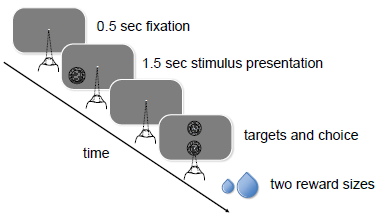

The signal strength of the stimulus ('Dc' in the 'Trials' field) may affect the eye-data, so it may be necessary to use trials with the same signal strength. 

We often use the 0% signal trials for our analysis, where there is no correct choice defined and monkeys are rewarded randomly. To get trials with the 0% signals, use the following snipets:

% get only 0% signal trials
noise_trials = completed_trials([completed_trials.Dc]==0);

## *Choice*

Subjects' choice behavior may not affect the eye-data during the fixation (stimulus presentation) period. Nonetheless, I write down snipets to get trials with a type of choice as it is not explicitly stored in the ex-file.

% far choice = (near stimulus and NOT rewarded) or (far stimulus and rewarded)
far_choice_trials = completed_trials(([completed_trials.hdx] < 0 & [completed_trials.Reward]==-1)...
    | ([completed_trials.hdx] > 0 & [completed_trials.Reward]==1));
% near choice = (near stimulus and rewarded) or (far stimulus and NOT rewarded)
near_choice_trials = ex.Trials(([completed_trials.hdx] < 0 & [completed_trials.Reward]==1)...
    | ([completed_trials.hdx] > 0 & [completed_trials.Reward]==-1));

Here 'hdx' is the depth of the disparity stimulus (negative: near stimulus, positive: far stimulus). 'Reward' is the field showing whether subjects got rewarded (1) or not (-1). 0 is given in this field if subjects made a fixation break.

## *Choice correctness*

Similarly, you can get trials with correct or error.

% correct trials
correct_trials = completed_trials([completed_trials.Reward]==1);
% error trials
error_trials = completed_trials([completed_trials.Reward]==-1);

## *Reward size*

Available reward size is increased when subjects made consecutive correct choices in the following manner. 

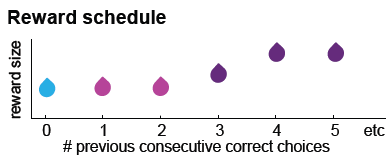 

You can check the reward size by 'ex.Trials(i).RewardSize'. As the baseline reward size may differ between sessions, you might want to use the following snipets to get the trial-by-trial available reward condition. I assume you excluded any fixation break trials.

len_comp = length(completed_trials);

% available reward size category (0: small, 1: medium, 2: large) in the completed trials
AvailableReward = zeros(1, len_comp);
for i = 4:len_comp
    % medium size of available reward
    if completed_trials(i-3).Reward==1 && completed_trials(i-2).Reward==1 && completed_trials(i-1).Reward==1
        AvailableReward(i) = 1;
    end
    % large size of available reward
    if i > 4 && completed_trials(i-4).Reward==1 && completed_trials(i-3).Reward==1 && completed_trials(i-2).Reward==1 && completed_trials(i-1).Reward==1
        AvailableReward(i) = 2;
    end
end

written by Katsuhisa Kawaguchi (21.03.18): katsuhisa.kawaguchi@uni-tuebingen.de